# Computational Methods

- Truncation error & round off error

- Numerical differentiation

- Numerical Integration

- Numerical solution of system of linear algebric equations

- Numerical solution of nonlinear algebric equation

- Numerical solution of ODEs

# Truncation Error & Round Off Error

Taylor's Series is: $f\left(x+h\right)=f\left(x\right)+hf^1 \left(x\right)+\frac{h^2 }{2_{\bullet }^| }f^2 \left(x\right)+\frac{h^3 }{3_{\bullet }^| }f^3 \left(x\right)+\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \frac{h^n }{n_{\bullet }^| }f^n \left(x\right)+O\left(h^{n+1} \right)$

In the above series if we consider upto the term containing $h^n$ then this will result to a truncation error of order $h^{n+1}$

Which implies truncation error depends on two factors in general $h$(Step size) and $n$ (depends on number of terms considered)

It is expected that if the step size is small error will be less & If the number of terms considered is more error will be less

But if the step size h is too small such that expressions depends on h may become too small even lower than machine precision then round off errors may accumulate and can increase the overall error with decreasing h. 

Therefore in numerical analysis selecting h(step size) should be optimum.

## Example Problem: 

Find the value of $e^a$ numerical method at a=0.1. Then check the variation of truncation error with n=1 to 10.

Solution: We know $e^a =1+a+\frac{a^2 }{2_{\bullet }^| }+\frac{a^3 }{3_{\bullet }^| }+\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \frac{a^n }{n_{\bullet }^| }+O\left(a^{n+1} \right)$  This can be easily proved from Taylo's Series.

Let us first find out the true value of $e^a$ at a=0.1

a=0.1;
trueVal=exp(a)

trueVal = 1.1052

Now Numerically calculate $e^a$ at a=0.1 for n=1 to 10

a=0.1;
n=10;
terms=[];
powerVec=[1:n]

powerVec =      1     2     3     4     5     6     7     8     9    10


   
terms=a.^powerVec./cumprod(powerVec)

terms =     0.1000    0.0050    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


numVal=1+cumsum(terms)

numVal =     1.1000    1.1050    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052    1.1052


trueVal=exp(a);

Now calculate truncation errors and plot with n

truncError=abs(trueVal-numVal)

truncError =     0.0052    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


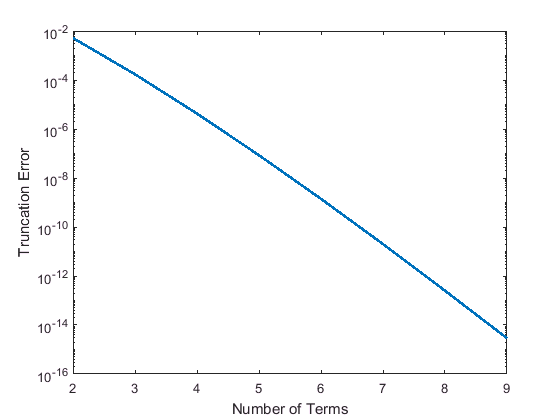

semilogy(powerVec+1,truncError,'LineWidth',2);
xlabel('Number of Terms');
ylabel('Truncation Error');

## Assignment Problem: 

Make a loglog plot in the same graph of the error with the variation of a =[0.1, 0.07, 0.04, 0.01] for n=1,2,3 and 4 

# Numerical Differentiation:

From Taylor's Series : $f\left(x+h\right)=f\left(x\right)+hf^1 \left(x\right)+\frac{h^2 }{2_{\bullet }^| }f^2 \left(x\right)+\frac{h^3 }{3_{\bullet }^| }f^3 \left(x\right)+\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \frac{h^n }{n_{\bullet }^| }f^n \left(x\right)+O\left(h^{n+1} \right)$


$$\frac{f\left(x+h\right)}{h}=\frac{f\left(x\right)+hf^1 \left(x\right)+\frac{h^2 }{2_{\bullet }^| }f^2 \left(x\right)+\frac{h^3 }{3_{\bullet }^| }f^3 \left(x\right)+\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \frac{h^n }{n_{\bullet }^| }f^n \left(x\right)+O\left(h^{n+1} \right)}{h}$$



$$\frac{f\left(x+h\right)}{h}=\frac{f\left(x\right)}{h}+f^1 \left(x\right)+\frac{h }{2_{\bullet }^| }f^2 \left(x\right)+O\left(h^2 \right)$$



$$f^1 \left(x\right)=\frac{f\left(x+h\right)−f\left(x\right)}{h}+O\left(h\right)$$


## For first derivative

Forward Difference Formula: $f^1 \left(x\right)=\frac{f\left(x+h\right)−f\left(x\right)}{h}+O\left(h\right)$

Backward Difference Formula: $f^1 \left(x\right)=\frac{f\left(x\right)−f\left(x−h\right)}{h}+O\left(h\right)$

Central Difference Formula: $f^1 \left(x\right)=\frac{f\left(x+h\right)−f\left(x−h\right)}{2h}+O\left(h^2 \right)$

## For 2nd derivative

Central difference formula: $f^2 \left(x\right)=\frac{f\left(x+h\right)−2f\left(x\right)+f\left(x−h\right)}{h^2 }+O\left(h^2 \right)$

## Example: 

Find out Numerical differentiation of ${tan}^{−1} x$ with respect to x at x=1. Take step size h=${10}^{−4}$  Also check the error associated in the numerical method with respect to true value.

Solution: we know $f\left(x\right)={tan}^{−1} x$, $f^1 \left(x\right)=\frac{1}{1+x^2 }$

Let us find out true value of $f^1 \left(x\right)$ at x=1

x=1;
trueVal_d=1/(1+x^2)

trueVal_d = 0.5000

Now do it Numerically

Case-1: Using forward difference formula

x=1;
h=1.0e-4;
fwd_d=(atan(x+h)-atan(x))/h;
fwd_err=abs(fwd_d-trueVal_d)

fwd_err = 2.4999e-05

Case-2: Using backward difference formula

bck_d=(atan(x)-atan(x-h))/h;
bck_err=abs(bck_d-trueVal_d)

bck_err = 2.5001e-05

Case-3: Using central difference formula

ctr_d=(atan(x+h)-atan(x-h))/(2*h);
ctr_err=abs(ctr_d-trueVal_d)

ctr_err = 8.3317e-10

## Assignment Problem: 

- Repeat the same problem in the example for h=$\left\lbrack {10}^{−1} ,\text{ }{10}^{−2} ,{10}^{−3} ,{10}^{−4} ,{10}^{−5} \right\rbrack$ and make a loglog plot of error with h for forward, backward & central difference method in a single graph. Make comment on the graph.

- If Temperature field in a rod(assume 1-D) is $T=−5x^3 +3x^2 +1$, and thermal conductivity is varying as $k=30+\sqrt{x}$, Plot the heat flux variation with x. Take x from 0 to 1m.

- Find second derivative of $f\left(x\right)=2−x+lnx$ at x=1. Also find the error in numerical calculation using central difference method.

## Solution 2.

heat flux=${q"}_x =−k\frac{\partial T}{\partial x}$

True heat flux ${\text{q"}}_x =\left(30+\sqrt{x}\right)∗\left(−15x^2 +6x\right)$

Let make  n=11 grid points equally spaced on the rod including two ends.

for any interior grid points we can use central difference formula because of high accuracy & liniear profile(less computation)

for left end point we are using forward difference & for right end point we are using backward difference formula.

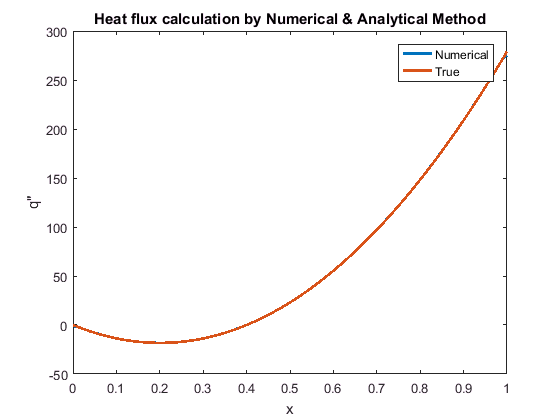



n=101;
x=linspace(0,1,n);
k=30+x.^0.5;
h=x(2)-x(1);
T=-5*x.^3+3*x.^2+1;
% True Heat Flux
q_flux_true=-k.*(-15*x.^2+6*x);
% Numerical Calculation of Heat Flux

%central difference
for i=2:n-1
dTdx(i)=(T(i+1)-T(i-1))/(2*h);
end
%Forward difference
dTdx(1)=(T(2)-T(1))/h;
%Backward Difference
dTdx(n)=(T(n)-T(n-1))/h;
%Heat Flux
q_flux_num=-k.*dTdx;

% Plot
plot(x,q_flux_num,x,q_flux_true,'LineWidth',2);
xlabel('x');
ylabel('q"');
legend('Numerical','True');
title('Heat flux calculation by Numerical & Analytical Method');